# How to draw a bifurcation diagram

This code draws the bifurcation diagram from Figure 3.3 of Goodman, R. H. [NLS bifurcations on the bowtie combinatorial graph and the dumbbell metric graph.](http://doi.org/10.3934/dcds.2019093) **Discrete & Continuous Dynamical Systems - A,** 39(4), 2203–2232 (2019). 

plus some extra branches to show how the code works.

We use 

- Six programs from the directory `source/continuation` which an end-user may simply run themselves

- Two programs from `source/examples` which an end-user could copy in creating their own project

Note how each of the routines outputs one or more identifiers that are used to call later routines that continue from points on the computed branches

## Construct the quantum graph and find the first few eigenfunctions

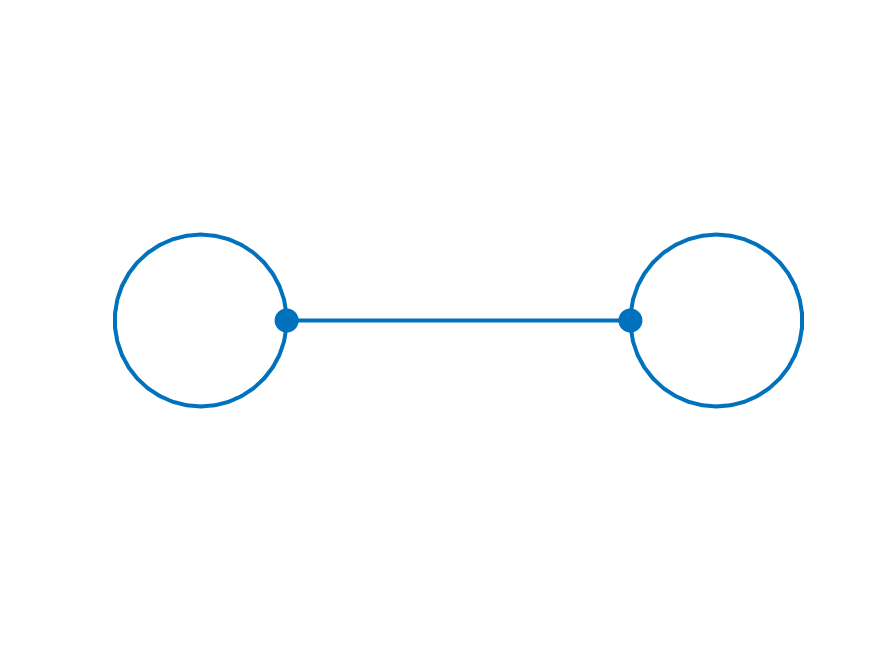

Created directory data/dumbbell/120.
Run number is 120.


tag='dumbbell';
L = [2*pi 4 2*pi];
nxvec=6;
Phi=quantumGraphFromTemplate(tag,'LVec',L,'nX',nxvec,'discretization','Uniform');
dataDir = makeContinuationDirectory(Phi,tag);

#### Compute and save some eigenfunctions

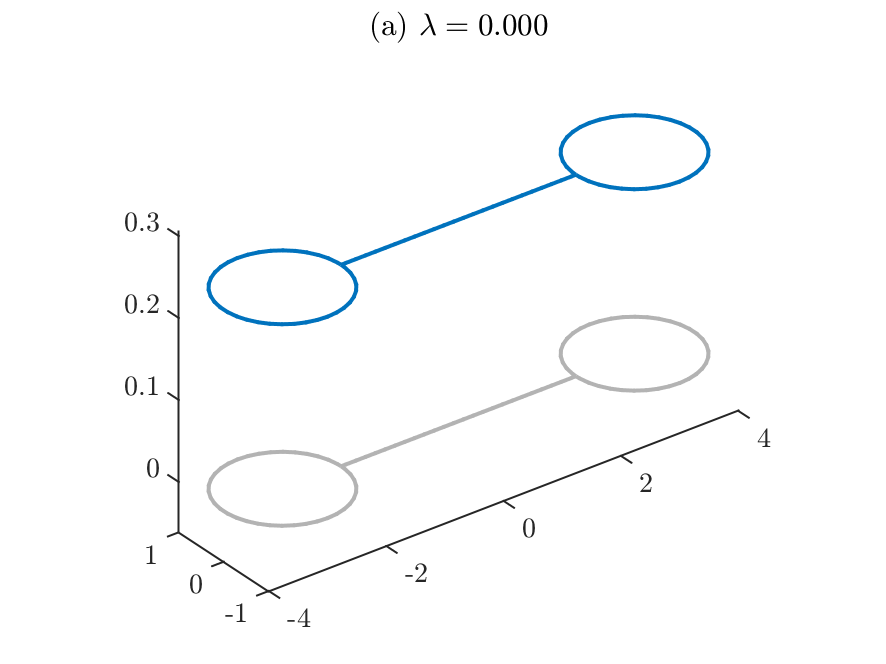

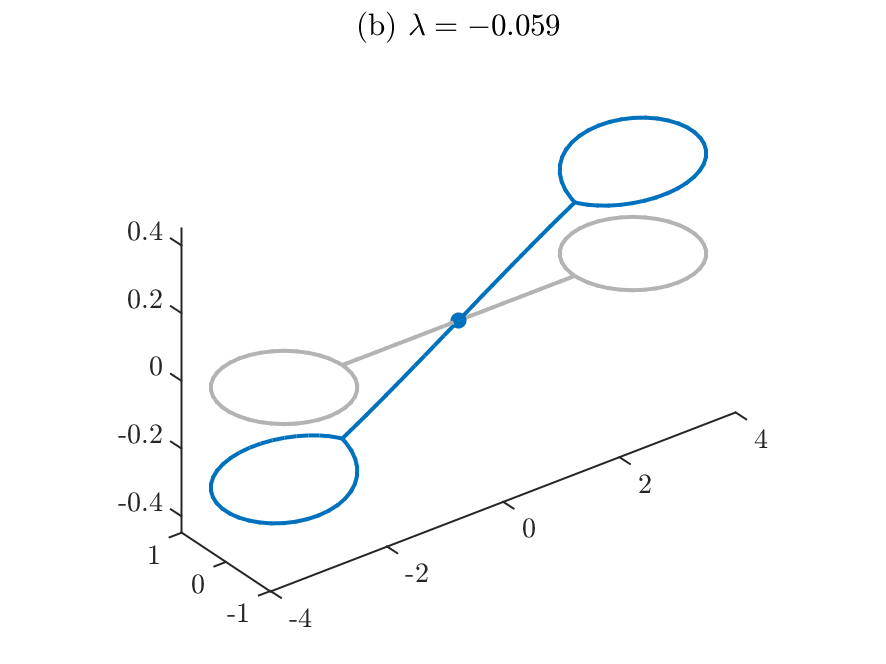

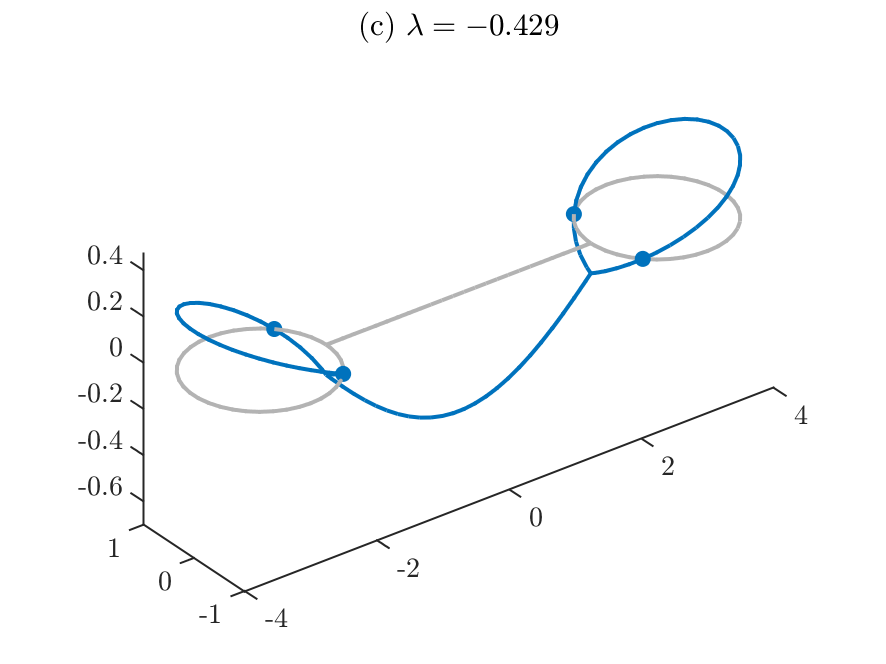

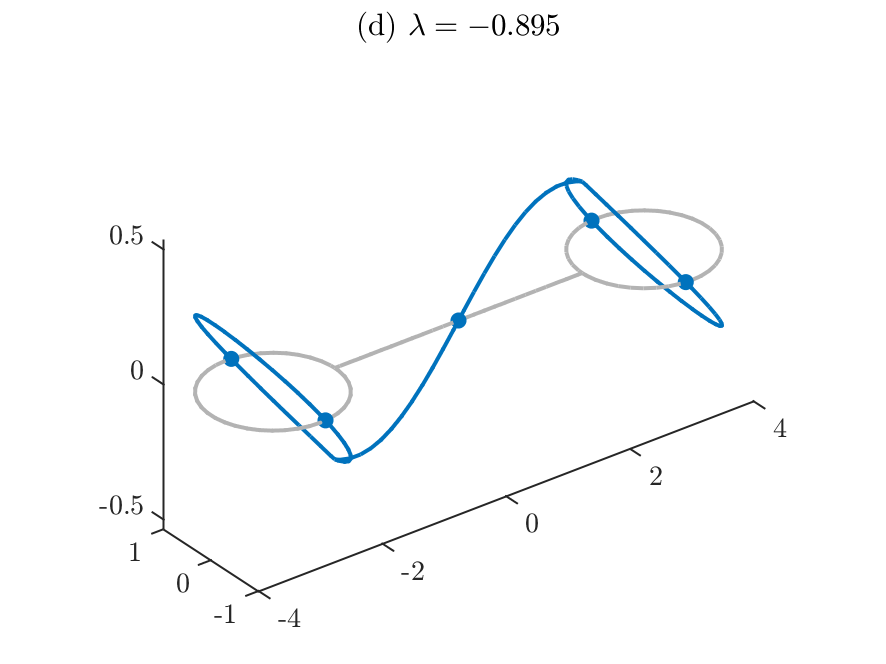

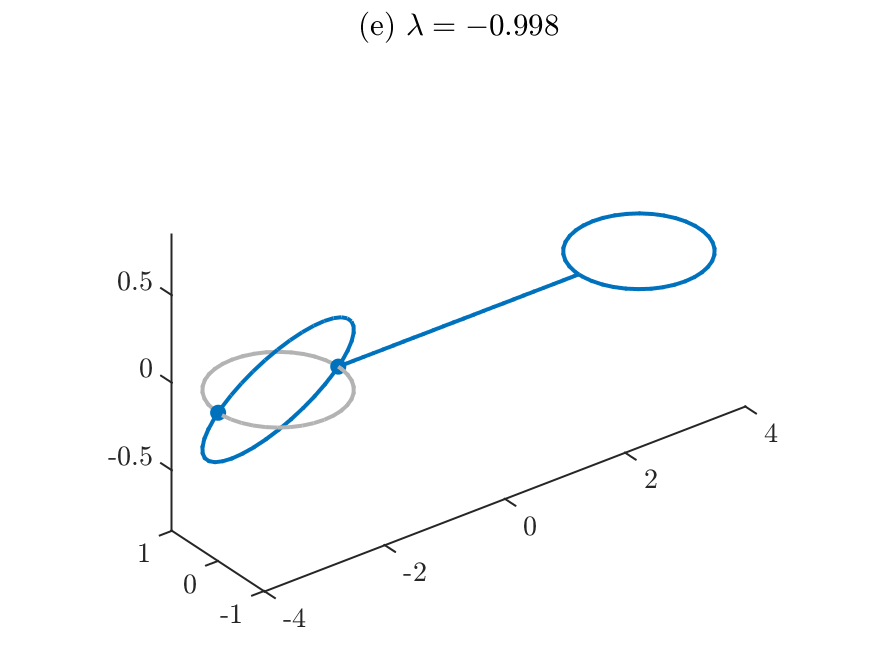

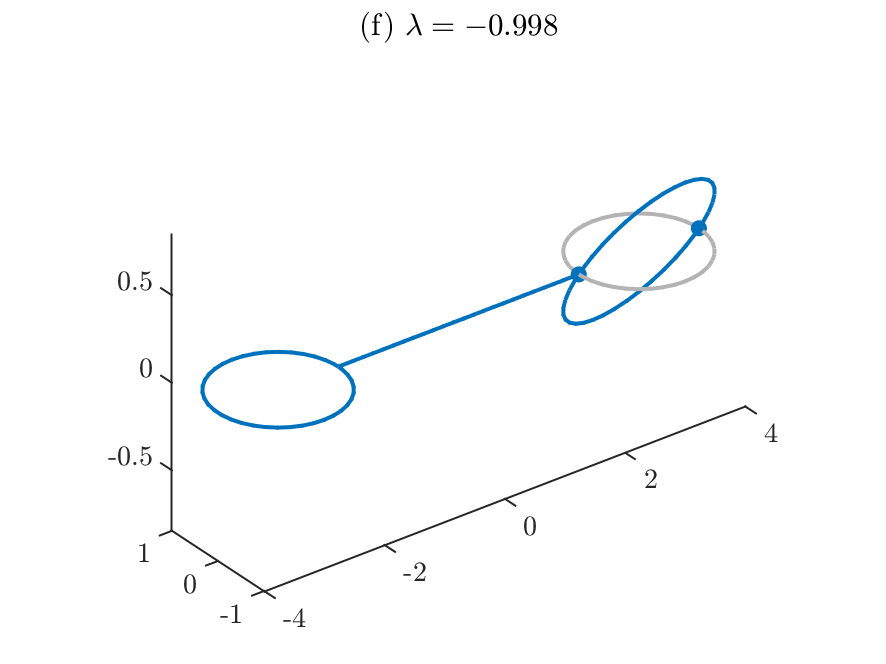

nToPlot=4;
nDoubles=1;
saveEigenfunctions(Phi,tag,dataDir,nToPlot,nDoubles);

#### Define the cubic nonlinearity and save it to the data directory. 

This must be a symbolic function of a single variable `z`. The default is $f(x)= 2z^3$, which is written out explicitly in this example. This function is  the default the argument `f` can be omitted.

syms z
f = 2*z^3;
fcns = saveNLSFunctionsGraph(dataDir,Phi,f);

## Compute branches that are continuation of the three least oscillatory eigenfunctions

- The function `continuerSet` acts like the MATLAB functions `odeset` and `optimset.` It sets a number of options that are used by the continuation programs

- The function `continueFromEig` continues a branch from the linear limit of an eigenfunction computed in the previous step

options=continuerSet([],'LambdaThresh',-3,'NThresh',9,'plotFlag',false,'minNormDelta',1e-3);
branch1=continueFromEig(dataDir,1,options);

N threshold crossed.
Branch number 1.
Data saved to directory data/dumbbell/120/branch001.
Branching Bifurcation at solution number 6.
Branching Bifurcation at solution number 9.
Branching Bifurcation at solution number 12.
Branching Bifurcation at solution number 14.


branch2=continueFromEig(dataDir,2,options);

Lambda threshold crossed.
Branch number 2.
Data saved to directory data/dumbbell/120/branch002.
No branching bifurcations found.


branch3=continueFromEig(dataDir,3,options);

N threshold crossed.
Branch number 3.
Data saved to directory data/dumbbell/120/branch003.
No branching bifurcations found.


## Compute some branches that bifurcate from this first branch

- The function `continueFromBranchpoint` continues a branch from the first branching bifurcation point. Since this is a symmetry-breaking bfirucation, we only need to continue in one direction, the branch stored in `branch1` at bifurcation location 1 

location=1;
direction=1;
branch4=continueFromBranchPoint(dataDir,branch1,location,direction,options);

Lambda threshold crossed.
Branch number 4.
Data saved to directory data/dumbbell/120/branch004.
No branching bifurcations found.


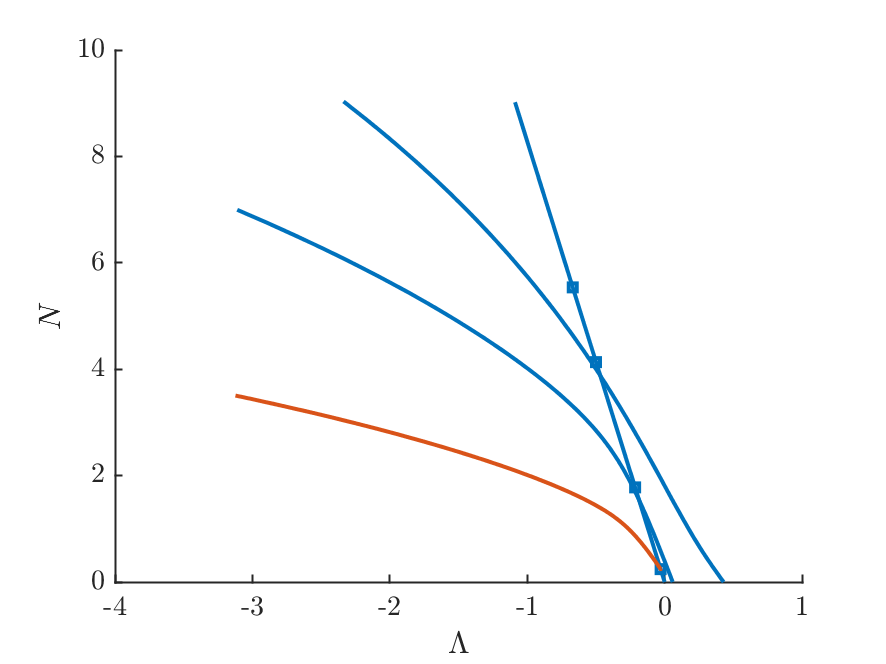

bifurcationDiagram(dataDir)

- The function `continueFromBranchpoint` continues a branch from the first branching bifurcation point. Since this is a transcritical bfirucation, we need to continue in both directions, the branch stored in `branch1` at bifurcation location 2

location=2;
direction=1;
branch5=continueFromBranchPoint(dataDir,branch1,location,direction,options);

Lambda threshold crossed.
Branch number 5.
Data saved to directory data/dumbbell/120/branch005.
Branching Bifurcation at solution number 21.


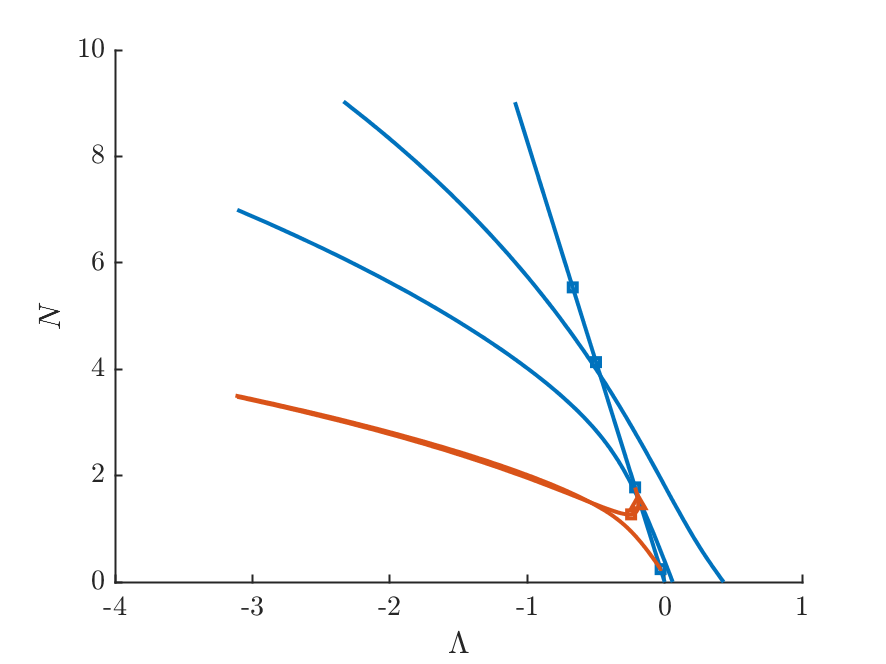

bifurcationDiagram(dataDir)

location=2;
direction=-1;
branch6=continueFromBranchPoint(dataDir,branch1,location,direction,options);

Lambda threshold crossed.
Branch number 6.
Data saved to directory data/dumbbell/120/branch006.
No branching bifurcations found.


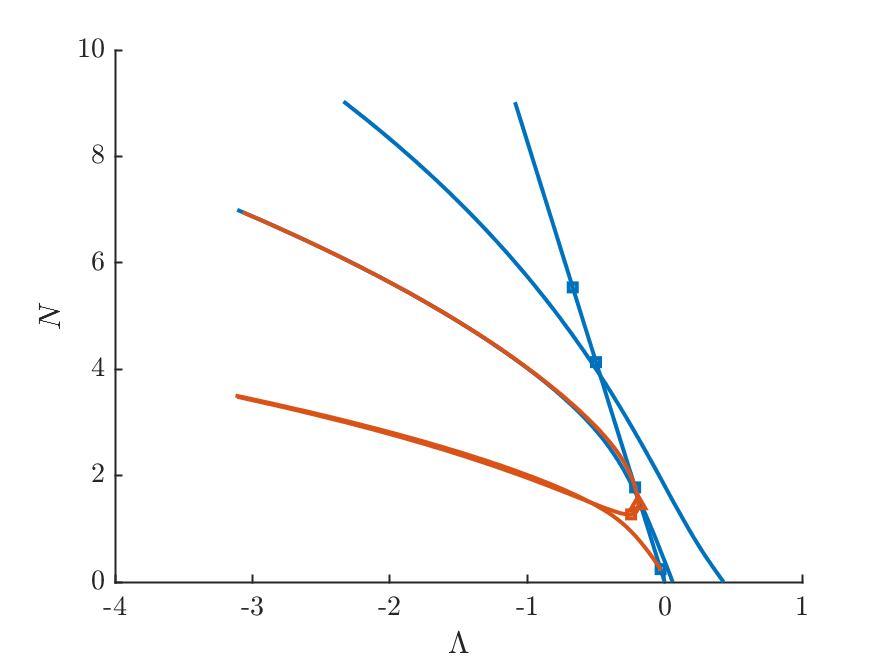

bifurcationDiagram(dataDir)

## Compute a branch that bifurcates from the third branch

Continues from the branch stored in `branch5` from the bifurcation point 1

location=1;
direction=1;
branch7=continueFromBranchPoint(dataDir,branch5,location,direction,options);

Lambda threshold crossed.
Branch number 7.
Data saved to directory data/dumbbell/120/branch007.
No branching bifurcations found.


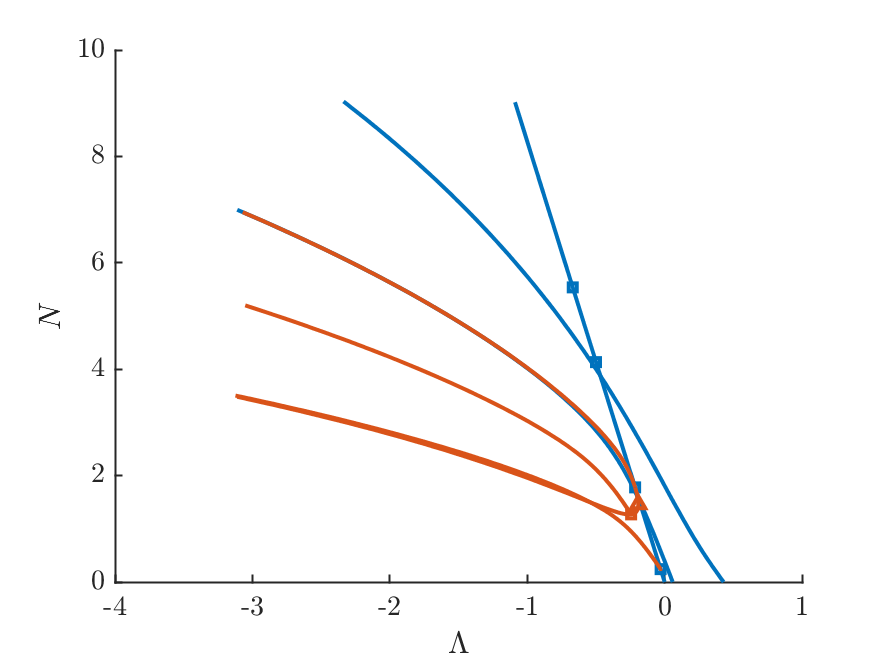

bifurcationDiagram(dataDir)

## Compute a large-amplitude solution, save it to a file, and compute its continuation

This seeds a standing wave with large frequency, localized and with positive amplitudes on edges 1 and 2.

Lambda0=-4;
edges=[1 2];
signs=[1 1];
filenumber=saveHighFrequencyStandingWave(dataDir,Lambda0,edges,signs);

File saved to data/dumbbell/120/savedFunction.001.
File number is 1. 


options=continuerSet(options,'LambdaThresh',-4.1,'NThresh',9);
direction=-1;
branch8=continueFromSaved(dataDir,filenumber,direction,options);

N threshold crossed.
Branch number 8.
Data saved to directory data/dumbbell/120/branch008.
No branching bifurcations found.


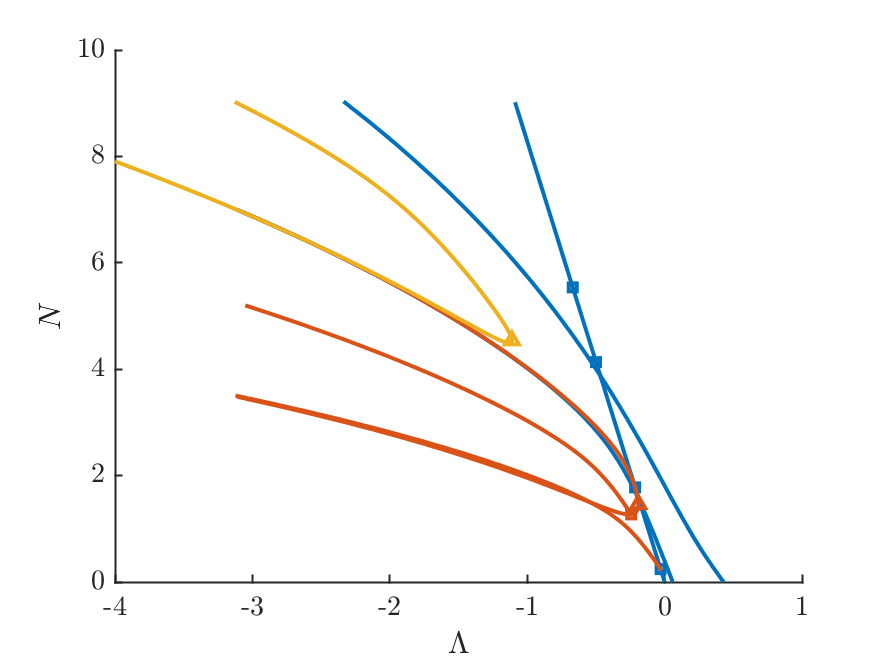

bifurcationDiagram(dataDir)

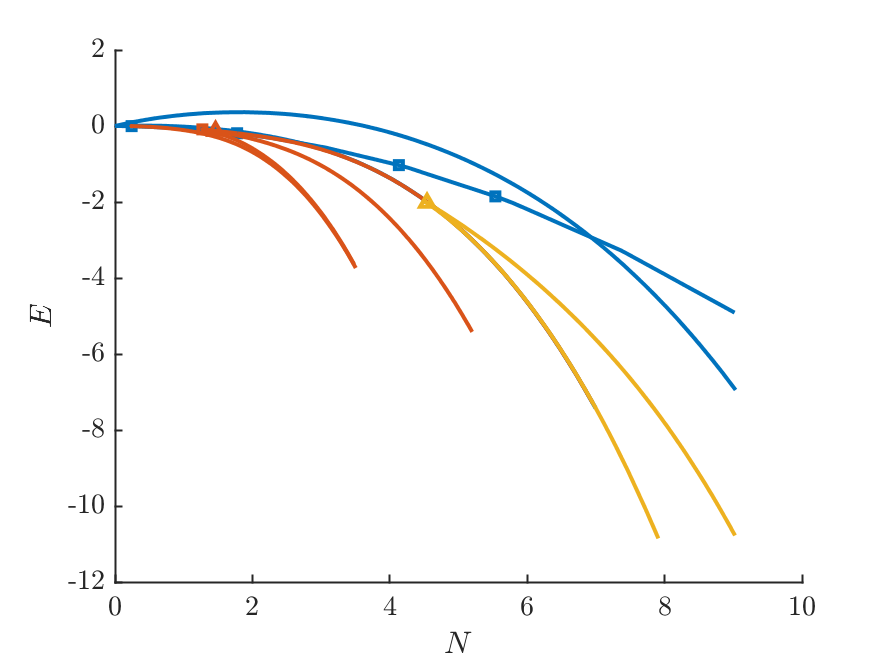

bifurcationDiagram(dataDir,'xAxis','N','yAxis','Energy')

## Extend a previously-computed branch

Continuation of the branch stored in branch`1.`

NExtra=2; LambdaExtra=2;
branch9=continueFromEnd(dataDir,branch1,'last',NExtra,LambdaExtra,options);

N threshold crossed.
Branch number 9.
Data saved to directory data/dumbbell/120/branch009.
Branching Bifurcation at solution number 4.


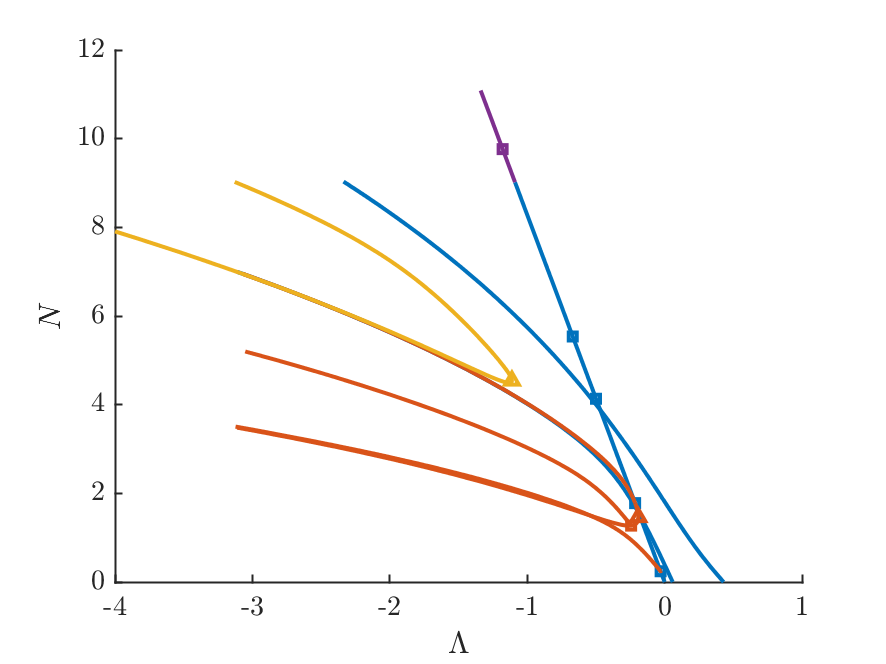

bifurcationDiagram(dataDir)

## Delete a branch

Delete a branch and it automatically disappears from the bifurcation diagram. We can remove the last computed branch. Equivalently, we could remove it by name with the command `rmBranch(dataDir,branch9)`.

rmBranch(dataDir,'last');
bifurcationDiagram(dataDir)

## Plot some solutions

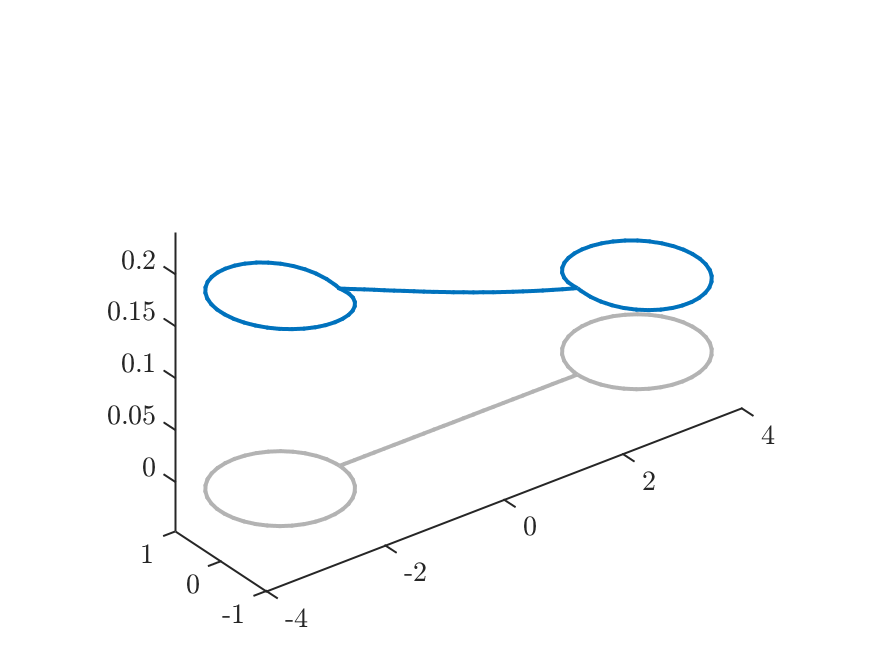

plotSolution(dataDir,branch4,15)

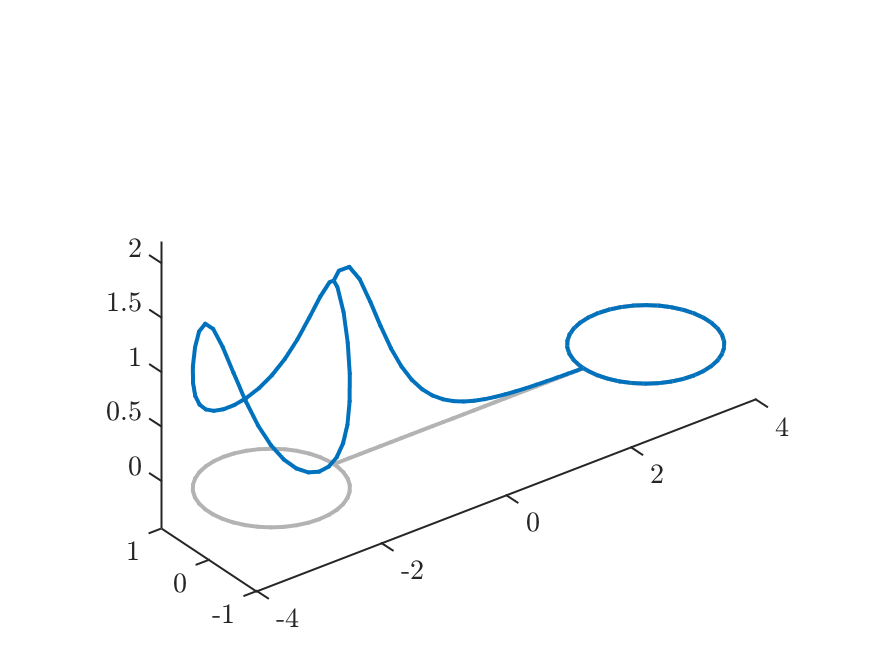

plotSolution(dataDir,branch8,'last')

## Animate all the solutions on a branch

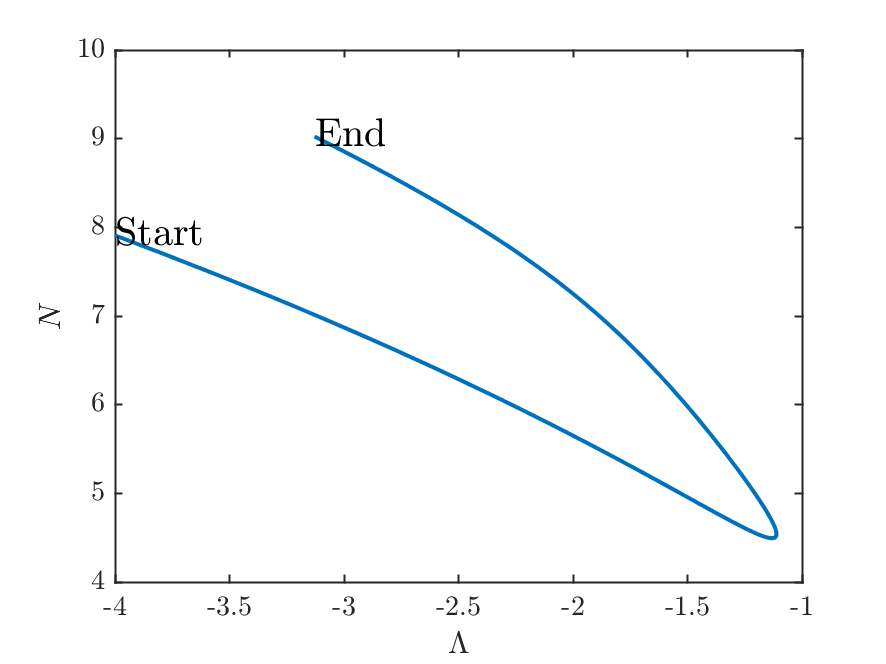

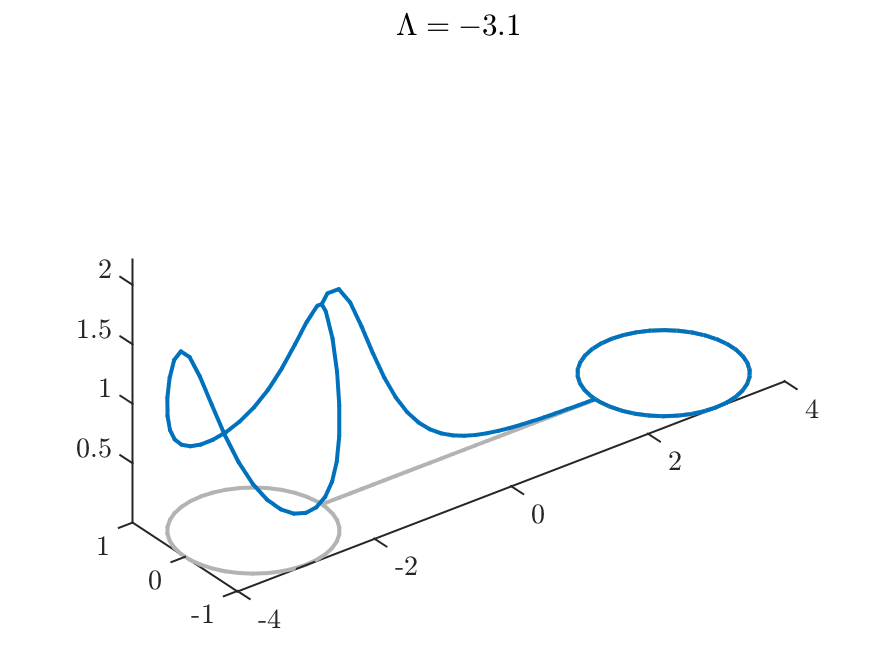

animateBranch(dataDir,branch8)

## Add a final comment to the log file

addComment(dataDir,'The contents of this directory illustrate the full use \nof the QGLABcontinuation codes.')